# 실습#3: 램버트 문제(Lambert's Problem)

**[2024-가을] 우주비행역학(ASE3080), 인하대학교 항공우주공학과**

**목성훈(shmok@inha.ac.kr)**

**2024.10.29**

% 초기화
clear all; 
close all;
clc;
format long

### 1. 최소 에너지 궤도(minimum energy orbit)

#### 1.1 시뮬레이션 환경

시뮬레이션 조건을 설정한다.

% constants
R2D             =   180/pi;
D2R             =   pi/180;
Mu_E            =   398600.4418;			% Earth gravitational constant			@WGS84
R_E             =   6378.137;				% Earth equatorial radius				@WGS84

% initial orbit
r1mag           =   7000;                       % [km] initial orbit radius
q1              =   -50 * D2R;
r1              =   [   r1mag * cos( q1 ) 
                        r1mag * sin( q1 ) 
                               0            ];
% target orbit
r2mag           =   7100;                       % [km] target orbit radius
q2              =   20 * D2R;
r2              =   [   r2mag * cos( q2 ) 
                        r2mag * sin( q2 ) 
                               0            ];

#### 1.2 최소 에너지 궤도

장반경을 시작으로 최소 에너지 천이 궤도를 구한다. (궤도 6요소)

% minimum energy orbit SMA
c               =   r2 - r1;                            % [km] position vector difference
cmag            =   norm( c );
a               =   1 / 4 * ( r1mag + r2mag + cmag )   % [km] semi-major axis

a =      5.546960647388886e+03


% mean anomaly difference, df
df              =   acos( ( r1mag^2 + r2mag^2 - cmag^2 ) / ( 2 * r1mag * r2mag ) );     % [rad] range of [ 0, pi , 제2 코사인법칙을 이용

% get e
cunit           =   c / cmag;
r1star_mag      =   2 * a - r1mag;                      % [km] distance between the unoccupied focus (F*) and r1
rFstar          =   r1 + r1star_mag * cunit;            % [km] position vector of F* 접할 때라서 c의 방향과 같다
e               =   norm( rFstar ) / ( 2 * a )          % eccentricity

e =    0.520651266677669


% get f1, f2
eunit           =   - rFstar / norm( rFstar );          % vector의 방향을 잘 고려한다.
r1unit          =   r1 / r1mag;
f1              =   acos( dot( eunit , r1unit ) );      % [rad] initial true anomaly, range of [ 0 , pi ]
f2              =   f1 + df;                            % [rad] final true anomaly, range of [ pi , 2 * pi ]
% get transfer time, dt
M1              =   CONV_f_to_M( f1 , e );              % [rad] initial mean anomaly
M2              =   CONV_f_to_M( f2 , e );              % [rad] final mean anomaly
dM              =   M2 - M1;
n               =   sqrt( Mu_E / a^3 );                 % [rad/s] mean orbital angular velocity
t2              =   dM / n                              % [s] transfer time mean anomaly = nt이기 때문에

t2 =      1.920882526431022e+03


% get v1
p               =   a * ( 1 - e^2 );                    % [km]      orbital parameter (radius at f = 90 deg)
h               =   sqrt( Mu_E * p );                   % [km2/s]   orbital angular momentum
f1dot           =   h / r1mag^2;
r1dot           =   p * e * f1dot * sin(f1) / ( 1 + e * cos(f1) )^2;
v1_PQW          =   [ r1dot * cos(f1) - r1mag * f1dot * sin(f1) ;
                      r1dot * sin(f1) + r1mag * f1dot * cos(f1) ;
                                          0                     ];
w               =   atan2( eunit(2), eunit(1) );        % [rad] argument of perigee
C_PQW2ECI       =   [ cos(w) -sin(w) 0 ; sin(w) cos(w) 0 ; 0 0 1 ];
v1              =   C_PQW2ECI * v1_PQW

v1 =    6.336148221141281
   1.371063255072990
                   0


% get v2
f2dot           =   h / r2mag^2;
r2dot           =   p * e * f2dot * sin(f2) / ( 1 + e * cos(f2) )^2;
v2_PQW          =   [ r2dot * cos(f2) - r2mag * f2dot * sin(f2) ;
                      r2dot * sin(f2) + r2mag * f2dot * cos(f2) ;
                                        0                       ];
v2              =   C_PQW2ECI * v2_PQW

v2 =   -4.665704187033022
   4.319000723089693
                   0


**위성 궤적**을 그려본다. 8-9차 수치 적분기를 이용한다.

% full and partial trajectory
x0 = [ r1 ; v1 ];
T = 2 * pi / n;
tspan = [ 0 T ]

tspan = 1.0e+03 *

                   0   4.111436695231243


tspan_partial = [ 0 t2 ]

tspan_partial = 1.0e+03 *

                   0   1.920882526431022


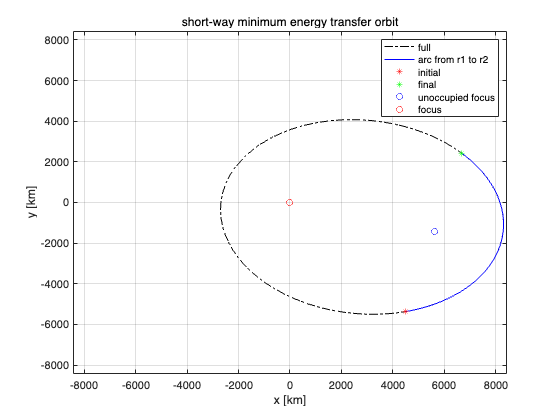

% propagate orbit using ode89
[t,x] = ode89(@(t,x) odeTwoBody_3D(t,x,Mu_E), tspan, x0);
ECIF_save = x';
[t_partial,x] = ode89(@(t,x) odeTwoBody_3D(t,x,Mu_E), tspan_partial, x0);
ECI_save = x';

% draw a figure
figure;
plot( ECIF_save( 1 , : ) , ECIF_save( 2 , : ), 'k-.' ); hold on; grid on;
plot( ECI_save( 1 , : ) , ECI_save( 2 , : ), 'b-' ); 
plot( r1( 1 ) , r1( 2 ), 'r*' );
plot( r2( 1 ) , r2( 2 ), 'g*' );
plot( rFstar( 1 ) , rFstar( 2 ), 'bo');
plot( 0 , 0, 'ro');
legend('full', 'arc from r1 to r2', 'initial', 'final', 'unoccupied focus', 'focus');
xlabel('x [km]'); ylabel('y [km]');
title('short-way minimum energy transfer orbit')
xlim( [ - a*(1+e) , a*(1+e) ] );
ylim( [ - a*(1+e) , a*(1+e) ] );

### 2. 램버트 천이(Lambert's transfer)

#### 2.1 시뮬레이션 환경

초기, 목표 위치는 이전과 같이 고정하되 천이 시간 $\Delta \;t$를 줄인다. 

% SMA and transfer time for minimum energy transfer
aminE = a

aminE =      5.546960647388886e+03


% tminE = t2
s = ( r1mag + r2mag + cmag ) / 2;
alpha = asin( sqrt( s / (2*a) ) ) * 2;
beta = asin( sqrt( (s - cmag) / (2*a) ) ) * 2;
tminE = sqrt(a^3 / Mu_E) * ( (alpha - sin(alpha)) - (beta - sin(beta)) )

tminE =      1.920882526431022e+03


tmax = tminE

tmax =      1.920882526431022e+03


% set a maximum SMA, amax
amax = s

amax =      1.109392129477777e+04


a = amax

a =      1.109392129477777e+04


alpha = asin( sqrt( s / (2*a) ) ) * 2;
beta = asin( sqrt( (s - cmag) / (2*a) ) ) * 2;
tmin = sqrt(a^3 / Mu_E) * ( (alpha - sin(alpha)) - (beta - sin(beta)) )

tmin =      9.279653691553851e+02


% compare to the transfer time from a parabolic orbit
tp = sqrt(2) / 3 * sqrt(s^3/Mu_E) * ( 1 - ((s-cmag)/s)^(3/2) )

tp =      7.494115656627291e+02


% set a transfer time
dt = 1500;

#### 2.2 이분법 기반 장반경 계산

이분법을 시작할 초기 장반경 구간을 설정한다. 

% set an initial SMA interval
amin = aminE

amin =      5.546960647388886e+03


amax = a

amax =      1.109392129477777e+04


% get the SMA using a bisection algorithm
da = amax - amin;
da_crit = 0.1;
while da > da_crit
    a = ( amin + amax ) / 2;
    alpha = asin( sqrt( s / (2*a) ) ) * 2;
    beta = asin( sqrt( (s - cmag) / (2*a) ) ) * 2;    
    f = sqrt(a^3 / Mu_E) * ( (alpha - sin(alpha)) - (beta - sin(beta)) );
    if f > dt
        amin = a;
    else
        amax = a;
    end
    da = amax - amin;
end
a

a =      5.775911583533706e+03


#### **2.3 초기 속도 계산**

% get v1 and v2
alpha = asin( sqrt( s / (2*a) ) ) * 2;
beta = asin( sqrt( (s - cmag) / (2*a) ) ) * 2;    
A = sqrt(Mu_E / 4 / a) * cot(alpha / 2);
B = sqrt(Mu_E / 4 / a) * cot(beta / 2);
v1 = (A+B) * c / cmag + (B-A) * r1 / r1mag

v1 =    6.066879878755294
   2.840419138766637
                   0


v2 = (A+B) * c / cmag - (B-A) * r2 / r2mag

v2 =   -3.680323454747131
   5.452174400440559
                   0


% get e and secondary focus
h           =   cross( r1, v1 );
evec        =   ( cross( v1 , h ) - Mu_E * r1 / r1mag) / Mu_E;     % eccentricity vector
e           =   norm( evec )   

e =    0.328875656808819


rFstar      =   -2 * a * evec;

#### 2.4 램버트 문제 해 검증

얻어진 초기 속도와 알고 있는 초기 위치로부터 2500초 간 적분한다. 목표 위치에 도달하는지 확인해 램버트 문제 해를 검증할 수 있다.

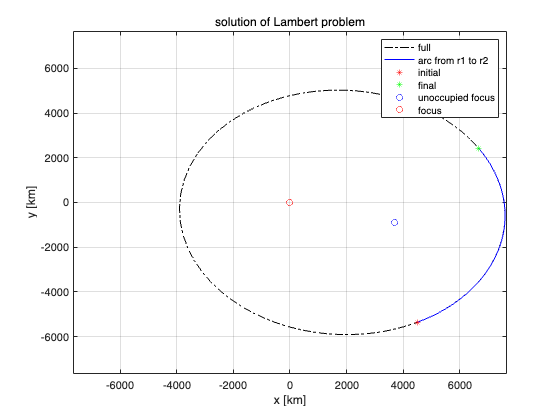

% full and partial trajectory
x0 = [ r1 ; v1 ];
n = sqrt(Mu_E / a^3);
T = 2 * pi / n;
tspan = [ 0 T ];
tspan_partial = [ 0 dt ];
% propagate orbit using ode89
[t,x] = ode89(@(t,x) odeTwoBody_3D(t,x,Mu_E), tspan, x0);
ECIF_save = x';
[t_partial,x] = ode89(@(t,x) odeTwoBody_3D(t,x,Mu_E), tspan_partial, x0);
ECI_save = x';

% draw a figure
figure;
plot( ECIF_save( 1 , : ) , ECIF_save( 2 , : ), 'k-.' ); hold on; grid on;
plot( ECI_save( 1 , : ) , ECI_save( 2 , : ), 'b-' ); 
plot( r1( 1 ) , r1( 2 ), 'r*' );
plot( r2( 1 ) , r2( 2 ), 'g*' );
plot( rFstar( 1 ) , rFstar( 2 ), 'bo');
plot( 0 , 0, 'ro');
legend('full', 'arc from r1 to r2', 'initial', 'final', 'unoccupied focus', 'focus');
xlabel('x [km]'); ylabel('y [km]');
title('solution of Lambert problem');
xlim( [ - a*(1+e) , a*(1+e) ] );
ylim( [ - a*(1+e) , a*(1+e) ] );

### 함수 정의

function M  =  CONV_f_to_M( f , e )

    % pre-processing, making f within [ 0 , 2 * pi )
    f           =   mod( f , 2 * pi );

    % conversion to E within [ 0 , 2 * pi )
    E           =   2 * atan( sqrt( ( 1 - e ) / ( 1 + e ) ) * tan( f / 2 ) );   % [ - pi , pi )
    E           =   mod( E , 2 * pi );                                          % [ 0 , 2 * pi )
    
    % conversion to M within [ 0 , 2 * pi )
    M           =   E - e * sin(E);
    
end
function xdot = odeTwoBody_3D(t,x,mu)
  
    % input
    r = x(1:3);
    v = x(4:6);
    rmag = norm(r);

    % derivative of state vector
    rdot = v;
    vdot = - mu / rmag^3 * r;
    xdot = [rdot ; vdot];
end